# Assignment 7 in OptReg

#### By Alexander Rambech

### Task 1

We have the Riccati equation, given by:

- 
$$P = Q + A^T P ( I + BR^{-1}B^TP)^{-1} A$$


The Sherman-Morrison-Woodbury formula is given by:

- 
$$F = (S + UTV)^{-1} = S^{-1}-S^{-1}U(T^{-1} + VS^{-1}U)^{-1}V^TS^{-1}$$


We want to compare $(T^{-1} + VS^{-1}U)^{-1}$ to $(R+B^TPB)^{-1}$, it seems wise to choose $S = I$, $T = R^{-1}$, $V = B^TP$ and $U = B$. Substituting this into $F$ yields:

- 
$$F = I - I B((R^{-1})^{-1}+B^TPIB)^{-1}B^TPI=I+B(R + B^TPB)^{-1}B^TP$$


Finally we substitute $F$ for $(I + BR^{-1} B^TP)^{-1}$ in the original Riccati equation:

- 
$$P = Q + A^T P ( I+B(R + B^TPB)^{-1}B^TP)^{-1} A$$


cleaning this up and solving for $0$ we have:

- 
$$A^TPA - P -A^TPB(R+B^TPB)^{-1}B^TPA + Q = 0$$


**QED. **:))

### Task 2

**a) **

%% Task 2a)
clear variables;

% Initialise continuous-time system
A_c = [0 1; -1 -1];
b_c = [0; 1];
T = 0.1;

% Initialise descrete-time system
A = eye(2) + T * A_c;
b = b_c*T;
C = [1 0];

% Initialise penalties
Q = [4 0; 0 4];
r = 1;

[K, P, eigen_values] = dlqr(A, b, Q, r);
K

K =     1.0373    1.6498


eigen_values

eigen_values =    0.8675 + 0.0531i
   0.8675 - 0.0531i


The feedback gain matrix is $K = [1.0373 ~ 1.6498]$ and that the eigen values are $\lambda = 0.8675 \pm 0.0531i$.

**b)**

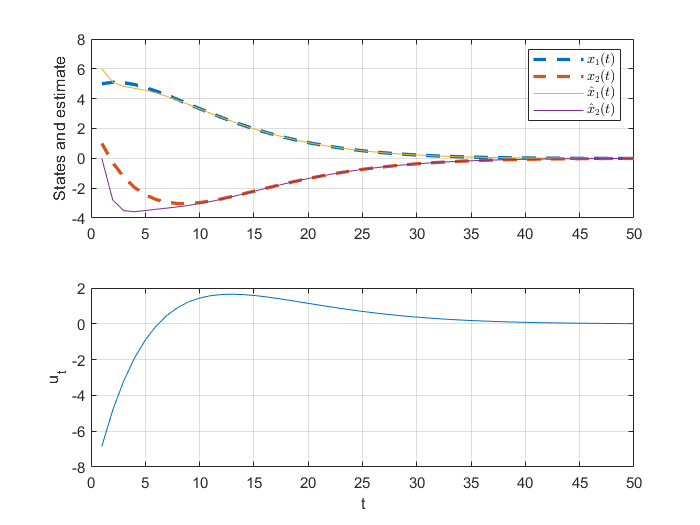

%% We use the same system as for a) 

% Initialising observer
poles = [0.5 + 0.03i; 0.5 - 0.03i];
K_f = place(A', C', poles).';

% Time steps
N = 50;

% Initialising storage vectors
x_sys = zeros(2, N);
x_hat = zeros(2, N);
y_sys = zeros(N, 1);
u = zeros(N, 1);

% Initial conditions
x_0 = [5; 1];
x_hat_0 = [6; 0];
x_sys(:, 1) = x_0;
x_hat(:, 1) = x_hat_0;

for i = 1:N
    u(i) = -K*x_sys(:, i);
    x_sys(:, i+1) = A*x_sys(:, i) + b*u(i);
    y_sys(i) = C*x_sys(:,i);
    x_hat(:, i+1) = A*x_hat(:, i) + b*u(i) + K_f*(y_sys(i) - C*x_hat(:, i));
end

x_sys(:, 51) = []; % Removing the 51st column
x_hat(:, 51) = []; % Removing the 51st column
t_vec = 1:N;

% For the plotting I have borrowed the plotter provided in the solution
figure(1);
subplot(2,1,1);
plot(t_vec, x_sys, '--', 'linewidth', 2); 
hold on;
plot(t_vec, x_hat, '-'); 
hold off;
hleg = legend('$x_1(t)$', '$x_2(t)$', '$\hat{x}_1(t)$', '$\hat{x}_2(t)$');
set(hleg, 'Interpreter', 'Latex');
grid('on');
box('on');
ylim([-4, 8]);
ylabel('States and estimate');
subplot(2,1,2);
plot(t_vec,u);
box('on');
grid('on');
ylim([-8, 2]);
ylabel('u_t');
xlabel('t');

We see by the first figure that the $\hat x_1$ estimate is follows it's corresponding state better than $\hat x_2$ does. This is because there are bigger changes in the second state. To minimize this error we can introduce faster poles.

**c)**

Finding the full state matrix and it's eigenvalues, is done simply with the code

%% Phi and eigenvalues
zero_mat = zeros(2);
size((b*K))

ans =      2     2


Phi = [A-b*K b*K; zero_mat A-K_f*C]

Phi =     1.0000    0.1000         0         0
   -0.2037    0.7350    0.1037    0.1650
         0         0    0.1000    0.1000
         0         0   -1.6090    0.9000


eig(Phi)

ans =    0.8675 + 0.0531i
   0.8675 - 0.0531i
   0.5000 + 0.0300i
   0.5000 - 0.0300i


We clearly see that the eigenvalues of the larger matrix $\Phi$ is the same as the system and observer combined.

### Task 3

**a)**

Here I am reusing MPC code from Assignment 6

%% MPC with x = x_hat and C = [1 0]

N = 10; % Length of time horizon
nx = size(A,2); % nx: number of states (equals the number of rows in A)
nu = size(b,2); % nu: number of controls (equals the number of rows in B)

% Cost function
I_N = eye(N);
Qt = diag([4 4]);
Q = kron(I_N, Qt);
Rt = 2;
R = kron(I_N, Rt);
G = blkdiag(Q, R);

% Equality constraint
Aeq_c1 = eye(N*nx);                         % Component 1 of A_eq
Aeq_c2 = kron(diag(ones(N-1,1),-1), -A);    % Component 2 of A_eq
Aeq_c3 = kron(I_N, -b);                     % Component 3 of A_eq
Aeq = [Aeq_c1 + Aeq_c2, Aeq_c3];

% Initialising equality model constraint
beq = [zeros(nx, 1); zeros((N-1)*nx,1)];

% Inequality constraints
x_lb = -Inf(N*nx,1);    % Lower bound on x
x_ub =  Inf(N*nx,1);    % Upper bound on x
u_lb = -4*ones(N*nu,1);   % Lower bound on u
u_ub =  4*ones(N*nu,1);   % Upper bound on u
lb = [x_lb; u_lb];      % Lower bound on z
ub = [x_ub; u_ub];      % Upper bound on z

% Set quadprog options
opt = optimset('Display','notify', 'Diagnostics','off', 'LargeScale','off', 'Algorithm', 'interior-point-convex');
size((A*x_0))

ans =      2     1


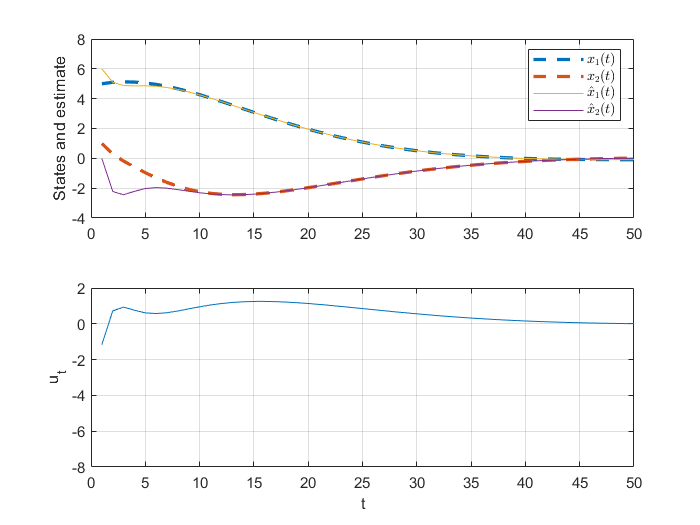

% Initialise final time
final_time = 50;

for i = 1:final_time
    
    % Update inequality constraint
    beq(1:nx) = A*x_hat(:, i);
    
    % Solving QP for horizon 10 each time step
    [z,fval,exitflag,output,lambda] = quadprog(G,[],[],[],Aeq,beq,lb,ub,[],opt);
    
    % Fetching the first element, as we only use this for control
    u_temp = z(N*nx+1:N*nx+N*nu);
    u(i) = u_temp(1);
    
    % The rest is the same as it was in task 2
    x_sys(:, i+1) = A*x_sys(:, i) + b*u(i);
    y_sys(i) = C*x_sys(:,i);
    x_hat(:, i+1) = A*x_hat(:, i) + b*u(i) + K_f*(y_sys(i) - C*x_hat(:, i));
end

x_sys(:, 51) = []; % Removing the 51st column
x_hat(:, 51) = []; % Removing the 51st column
t_vec = 1:final_time;

% For the plotting I have borrowed the plotter provided in the solution
figure(1);
subplot(2,1,1);
plot(t_vec, x_sys, '--', 'linewidth', 2); 
hold on;
plot(t_vec, x_hat, '-'); 
hold off;
hleg = legend('$x_1(t)$', '$x_2(t)$', '$\hat{x}_1(t)$', '$\hat{x}_2(t)$');
set(hleg, 'Interpreter', 'Latex');
grid('on');
box('on');
ylim([-4, 8]);
ylabel('States and estimate');
subplot(2,1,2);
plot(t_vec,u);
box('on');
grid('on');
ylim([-8, 2]);
ylabel('u_t');
xlabel('t');

We observe here that we get very different results in $u_t$ c%% ompared to the state feedback.

**b)**

We now do the same as in **a), **but with $C = 1$ and we use the open-loop model as feedback to the QP instead of the estimated $\hat x$.

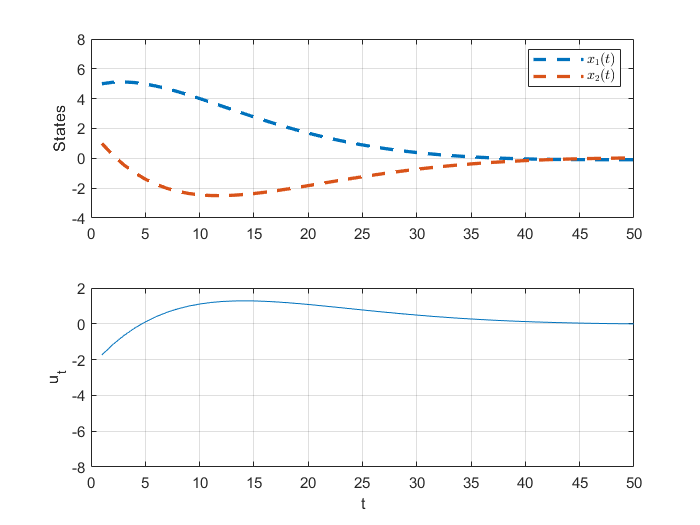

%% MPC with x = x_sys and C = I

% Updating C
C = eye(2);

% Expanding y
y_sys = zeros(2, N);

for i = 1:final_time
    
    % Update inequality constraint
    beq(1:nx) = A*x_sys(:, i);
    
    % Solving QP for horizon 10 each time step
    [z,fval,exitflag,output,lambda] = quadprog(G,[],[],[],Aeq,beq,lb,ub,[],opt);
    
    % Fetching the first element, as we only use this for control
    u_temp = z(N*nx+1:N*nx+N*nu);
    u(i) = u_temp(1);
    
    % The rest is the same as it was in task 2
    x_sys(:, i+1) = A*x_sys(:, i) + b*u(i);
    y_sys(:, i) = C*x_sys(:,i);
end

x_sys(:, 51) = []; % Removing the 51st column

% For the plotting I have borrowed the plotter provided in the solution
figure(1);
subplot(2,1,1);
plot(t_vec, x_sys, '--', 'linewidth', 2); 
hleg = legend('$x_1(t)$', '$x_2(t)$');
set(hleg, 'Interpreter', 'Latex');
grid('on');
box('on');
ylim([-4, 8]);
ylabel('States');
subplot(2,1,2);
plot(t_vec,u);
box('on');
grid('on');
ylim([-8, 2]);
ylabel('u_t');
xlabel('t');

Here we see we get a much smoother input squence $u_t$, this is due to us using the ideal model for the system instead of estimating the states.

### Task 4

**a)**

Using the code from task **2a) **we have

%% Task 4a)
clear variables;

% Initialise continuous-time system
A_c = [0 1; -1 -1];
b_c = [0; 1];
T = 0.1;

% Initialise descrete-time system
A = eye(2) + T * A_c;
b = b_c*T;
C = [1 0];

% Initialise penalties
Q = [4 0; 0 4];
r = 1;

[K, P, eigen_values] = dlqr(A, b, Q, r);
P

P =    55.0341   14.5426
   14.5426   20.4678


**b)**